# **DISEÑO 7**

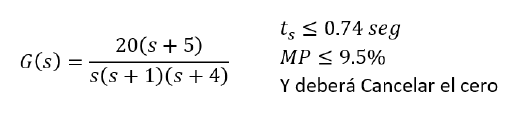

s=tf('s');
G=(20*(s+5))/(s*(s+1)*(s+4))

Ge=ss(G) %Para hallar la matriz de espacio de estados
A=Ge.a; B=Ge.b;C=Ge.c;D=Ge.d; %Separamos nuestras matrices
order(G)
Mc=rank(ctrb(A,B))

ts=0.74 %Ts deseado
mp=0.095; %Mp deseado
zeta=-log(mp)/(sqrt(pi^2+log(mp)^2))
wn=4/(zeta*ts) %% criterio del 2%
sigma=zeta*wn
wd=wn*sqrt(1-zeta^2)
sx=-sigma+wd*i %%polos deseados

%Escribir manualmente el valor de el polo
P=[sx sx']'
Pa=[P; -5]

k=acker(A,B,Pa) %Hallar compensador

Alc=A-B*k; %Retroalimentacion
Gc=ss(Alc,B,C,0) %Sistema compensado en ganancia
GC1=tf(Gc) %Pasamos de espacio de estados a TF

F=1/dcgain(Gc) %Precompensador

step(GC1*F) %Aplicamos precompensador
stepinfo(GC1)%Graficamos compensado 

